# Model manipulation

**Vanja Vlasov, with additions by Thomas Pfau**

In this tutorial, we will do a manipulation with the simple model of the first few reactions of the glycolisis metabolic pathway as created in the "Model Creation" tutorial. 

Glycolysis is the metabolic pathway that occurs in most organisms in the cytosol of the cell. First, we will use the beginning of that pathway to create a simple constraint-based metabolic network (Figure 1).

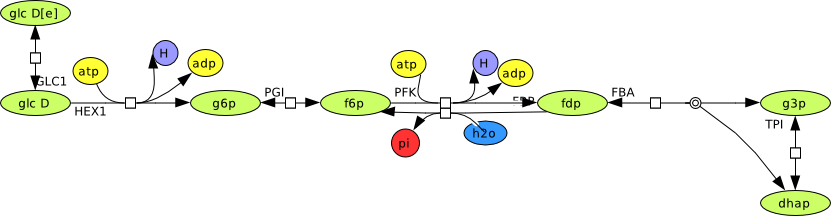

                                                                   Figure 1: A small metabolic network consisting of the seven reactions in the glycolisis pathway. 

At the beginning of the reconstruction, an integrity of the draft reconstruction must be initially assessed. The accuracy of the stochiometry, necessity of each reaction and metabolite, direction and reversibility of the reactions needed to be evaluated. 

After creating or loading the model, the model can be modified to simulate different conditions, such as:

- Creating, adding and handling reactions;

- Adding Exchange, Sink and Demand reactions;

- Altering reaction bounds;

- Altering Reactions;

- Remove reactions and metabolites;

- Search for duplicates and comparison of two models;

- Changing the model objective;

- Changing the direction of reaction(s);

Start CobraToolbox

initCobraToolbox



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2017
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done.
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules ... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > Retrieving models ...   Done.
 > TranslateSBML is installed and working properly.
 > Configuring sol

warning on
warning off MATLAB:subscripting:noSubscriptsSpecified 

## Generate a network

A constraint-based metabolic model contains the stoichiometric matrix with reactions and metabolites [1].

*S* is stoichiometric representation of metabolic networks corresponding to the reactions in the biochemical pathway. In an each column  of the *S *is a biochemical reaction and in each row is a precise metabolite. There is a stoichiometric coefficient of zero, which means that metabolite not participate in that distinct reaction. The coefficient also can be positive when the appropriate metabolite is produced, or negative for every metabolite depleted [1].

ReactionFormulas = {'glc-D[e]  -> glc-D[c]',...
    'glc-D[c] + atp[c]  -> H[c] + adp[c] + g6p[c]',...
    'g6p[c]  <=> f6p[c]',...
    'atp[c] + f6p[c]  -> H[c] + adp[c] + fdp[c]',...
    'fdp[c] + h2o[c]  -> f6p[c] + pi[c]',...
    'fdp[c]  -> g3p[c] + dhap[c]',...
    'dhap[c]  -> g3p[c]'};
ReactionNames = {'GLCt1','HEX1','PGI','PFK','FBP','FBA','TPI'};
lowerbounds = [-20, 0, -20, 0, 0,-20,-20];
upperbounds = [20, 20, 20, 20, 20, 20, 20];
model = createModel(ReactionNames,ReactionNames,ReactionFormulas,...
                   'lowerBoundList',lowerbounds,'upperBoundList',upperbounds);

GLCt1	glc-D[e] 	<=>	glc-D[c] 


HEX1	glc-D[c] + atp[c] 	->	H[c] + adp[c] + g6p[c] 


PGI	g6p[c] 	<=>	f6p[c] 


PFK	atp[c] + f6p[c] 	->	H[c] + adp[c] + fdp[c] 


FBP	fdp[c] + h2o[c] 	->	f6p[c] + pi[c] 


FBA	fdp[c] 	<=>	g3p[c] + dhap[c] 
TPI	dhap[c] 	<=>	g3p[c] 


We can now have a look at the different model fields created. The stoichiometry is stored in the S field of the model, which was described above. Since this is commonly a sparse matrix (i.e. it does contain a lot of zeros, to display it it is useful to use the full representation)

full(model.S)

ans =     -1     0     0     0     0     0     0
     1    -1     0     0     0     0     0
     0    -1     0    -1     0     0     0
     0     1     0     1     0     0     0
     0     1     0     1     0     0     0
     0     1    -1     0     0     0     0
     0     0     1    -1     1     0     0
     0     0     0     1    -1    -1     0
     0     0     0     0    -1     0     0
     0     0     0     0     1     0     0


Some descriptive fields always present are model.mets and model.rxns which represent the metabolites and the reactions respectively. 

model.mets

ans =     'glc-D[e]'
    'glc-D[c]'
    'atp[c]'
    'H[c]'
    'adp[c]'
    'g6p[c]'
    'f6p[c]'
    'fdp[c]'
    'h2o[c]'
    'pi[c]'
    'g3p[c]'
    'dhap[c]'


model.rxns

ans =     'GLCt1'
    'HEX1'
    'PGI'
    'PFK'
    'FBP'
    'FBA'
    'TPI'


Fields in the COBRA model are commonly column vectors, which can be an important detail when writing functions manipulating these fields.

There are a few more fields present in each COBRA model:

model.lb, indicating the lower bounds of each reaction, and model.ub indicating the upper bound of a reaction.

[{'Reaction ID','Lower Bound','Upper Bound'};...    % this displays an array with
 model.rxns,num2cell(model.lb), num2cell(model.ub)] % reaction names and flux bounds. 

ans =     'Reaction ID'    'Lower Bound'    'Upper Bound'
    'GLCt1'          [        -20]    [         20]
    'HEX1'           [          0]    [         20]
    'PGI'            [        -20]    [         20]
    'PFK'            [          0]    [         20]
    'FBP'            [          0]    [         20]
    'FBA'            [        -20]    [         20]
    'TPI'            [        -20]    [         20]


printFluxBounds(model); %This is a convenience function which does 

Reaction ID	   Lower Bound	   Upper Bound
      GLCt1	       -20.000	        20.000
       HEX1	         0.000	        20.000
        PGI	       -20.000	        20.000
        PFK	         0.000	        20.000
        FBP	         0.000	        20.000
        FBA	       -20.000	        20.000
        TPI	       -20.000	        20.000


                        %pretty much the same as the line above

Before we start to modify the model, it might be useful to store some of the current properties of the model

mets_length = length(model.mets);
rxns_length = length(model.rxns);

## Creating, adding and handling reactions

If we want to add a reaction to the model or modify an existing reaction we are using function addReaction. 

We will add some more reactions from glycolysis.

- The formula approach

model = addReaction(model, 'GAPDH',...
       'reactionFormula', 'g3p[c] + NAD[c] + 2 pi[c] -> NADH[c] + H[c] + 13bpg[c]');

GAPDH	2 pi[c] + g3p[c] + NAD[c] 	->	H[c] + NADH[c] + 13bpg[c] 


model = addReaction(model, 'PGK',...
       'reactionFormula', '13bpg[c] + adp[c] -> atp[c] + 3pg[c]');

PGK	adp[c] + 13bpg[c] 	->	atp[c] + 3pg[c] 


model = addReaction(model, 'PGM', 'reactionFormula', '3pg[c] <=> 2pg[c]' );

PGM	3pg[c] 	<=>	2pg[c] 


Display of stoichiometric matrix after adding reactions. Note the enlarge link when you move your mouse over the output to display rthe full matrix:

full(model.S) 

ans =     -1     0     0     0     0     0     0     0     0     0
     1    -1     0     0     0     0     0     0     0     0
     0    -1     0    -1     0     0     0     0     1     0
     0     1     0     1     0     0     0     1     0     0
     0     1     0     1     0     0     0     0    -1     0
     0     1    -1     0     0     0     0     0     0     0
     0     0     1    -1     1     0     0     0     0     0
     0     0     0     1    -1    -1     0     0     0     0
     0     0     0     0    -1     0     0     0     0     0
     0     0     0     0     1     0     0    -2     0     0


% one extra column is added(for added reaction) and 5 new 
% rows(for NADH, NAD, 13bpg, 2pg and 3pg metabolites)

The following functions are used when we want to search reactions sequence in the model and change the order of the selected reaction.

rxnID = findRxnIDs(model, model.rxns);

model = moveRxn(model, 8, 1);

While the latter does not modify the structure as such it can help in keeping a model tidy.

- The list approach

 The addReaction function has ability to recognize duplicate reactions when an order of metabolites and an abbreviation of the reaction are different.

model = addReaction(model, 'GAPDH2',...
    'metaboliteList', {'g3p[c]', 'NAD[c]', 'pi[c]', '13bpg[c]', 'NADH[c]','H[c]' },...
    'stoichCoeffList', [-1; -1; -2; 1; 1; 1], 'reversible',false);

Since the second call should not have added anything we will check if the number of the reaction increased by the three reactions we added (and not by the one duplicated) and the number of metabolites was incremented by five (13bpg, NAD, NADH, 23bpg and 2pg).

assert(length(model.rxns) == rxns_length + 3);
assert(length(model.mets) == mets_length + 5);

## Adding Exchange, Sink and Demand reactions

Specific type of reactions in the constraint-based models are reactions that are using and recycling accumulated metabolites, or producing required metabolites in the model.

- *Exchange reactions *-  Reactions added to the model to move metabolites across the created *in silico *compartments. Those compartments represent intra- and intercellular membranes.

- *Sink reactions* - The metabolites, produced in reactions that are outside of an ambit of the system or in unknown reactions, are supplied to the network with reversible sink reactions.

- *Demand reactions* - Irreversible reactions added to the model to consume metabolites that are deposited in the system.

There are two ways to implement that kind of reactions:

- **Use addReaction with the documented function call:**

model = addReaction(model, 'EX_glc-D[e]', 'metaboliteList', {'glc-D[e]'} ,...
                    'stoichCoeffList',[-1]);

EX_glc-D[e]	glc-D[e] 	<=>	


    In the bigger networks we can find our exchange reactions with the following functions:

[selExc,selUpt] = findExcRxns(model, 0, 1) % determines whether a reaction is a

selExc =    0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1


selUpt =    0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


                                           % general exchange reaction and whether 
                                           % its an uptake.

         **2.  Use a utility function to create a particular reaction type: addExchangeRxn, addSinkReactions, addDemandReaction.**

model = addExchangeRxn(model, {'glc-D[e]','glc-D[c]'})

EX_glc-D[e]	glc-D[e] 	<=>	
EX_glc-D[c]	glc-D[c] 	<=>	


model =           rxns: {12×1 cell}
             S: [17×12 double]
            lb: [12×1 double]
            ub: [12×1 double]
             c: [12×1 double]
          mets: {17×1 cell}
             b: [17×1 double]
         rules: {12×1 cell}
         genes: {0×1 cell}
        osense: -1
        csense: [17×1 char]
    rxnGeneMat: [12×0 double]
      rxnNames: {12×1 cell}
    subSystems: {12×1 cell}
      metNames: {17×1 cell}
       grRules: {12×1 cell}


model = addSinkReactions(model, {'13bpg[c]', 'NAD[c]'})

sink_13bpg[c]	13bpg[c] 	<=>	
sink_NAD[c]	NAD[c] 	<=>	


model =           rxns: {14×1 cell}
             S: [17×14 double]
            lb: [14×1 double]
            ub: [14×1 double]
             c: [14×1 double]
          mets: {17×1 cell}
             b: [17×1 double]
         rules: {14×1 cell}
         genes: {0×1 cell}
        osense: -1
        csense: [17×1 char]
    rxnGeneMat: [14×0 double]
      rxnNames: {14×1 cell}
    subSystems: {14×1 cell}
      metNames: {17×1 cell}
       grRules: {14×1 cell}


 model = addDemandReaction(model, {'dhap[c]', 'g3p[c]'})

DM_dhap[c]	dhap[c] 	->	
DM_g3p[c]	g3p[c] 	->	


model =           rxns: {16×1 cell}
             S: [17×16 double]
            lb: [16×1 double]
            ub: [16×1 double]
             c: [16×1 double]
          mets: {17×1 cell}
             b: [17×1 double]
         rules: {16×1 cell}
         genes: {0×1 cell}
        osense: -1
        csense: [17×1 char]
    rxnGeneMat: [16×0 double]
      rxnNames: {16×1 cell}
    subSystems: {16×1 cell}
      metNames: {17×1 cell}
       grRules: {16×1 cell}


## Setting ratio between the reactions and changing reactions boundary

It is important to emphasize that previous knowledge base informations should be taken into account. Most of them could disrupt future analysis of the model. 

For instance, if it is familiar that flux through one reaction is *X* times the flux through another reaction, it is recommended to specify that in your model. 

 E.g. $1\text{ }v\text{ }EX_glc−D\left\lbrack c\right\rbrack =2\text{ }v\text{ }EX_glc−D\left\lbrack e\right\rbrack$

model = addRatioReaction (model, {'EX_glc-D[c]','EX_glc-D[e]'}, [1; 2]);

## **Altering Reaction bounds**

In order to respect the transport and exchange potential of a particular metabolite, or to resemble the different conditions in the model, we frequently need to set appropriate limits of the reactions.

model = changeRxnBounds(model, 'EX_glc-D[e]', -18.5, 'l');

## Modifiying Reactions

The addReaction function also is a good choice when modifying reactions. By supplying a new stoichiometry, the old will be overwritten. For example further up, we added awrong stoichiometry for the GAP-Dehydrogenase with a phosphate coefficient of 2. (easily visiple by printing the reaction)

printRxnFormula(model,'rxnAbbrList','GAPDH');

GAPDH	2 pi[c] + g3p[c] + NAD[c] 	->	H[c] + NADH[c] + 13bpg[c] 


We can correct this by simply calling ddReaction again with the corrected stoichiometry. In essence parts which are not provided are taken from the old reaction, and only the new ones overwrite the existing data

model = addReaction(model, 'GAPDH',...
    'metaboliteList', {'g3p[c]', 'NAD[c]', 'pi[c]', '13bpg[c]', 'NADH[c]','H[c]' },...
    'stoichCoeffList', [-1; -1; -1; 1; 1; 1]);

GAPDH	pi[c] + g3p[c] + NAD[c] 	->	H[c] + NADH[c] + 13bpg[c] 


We might also want to add a gene rule to the reaction. this can either be done using 

model = changeGeneAssociation(model,'GAPDH','G1 and G2');

New gene G1 added to model
New gene G2 added to model


printRxnFormula(model,'rxnAbbrList',{'GAPDH'},'gprFlag',true);

GAPDH	pi[c] + g3p[c] + NAD[c] 	->	H[c] + NADH[c] + 13bpg[c] 	G1 and G2


The other option to achieve this is to use addReaction and the geneRule parameter 

model = addReaction(model,'PGK','geneRule','G2 or G3', 'printLevel', 0);

New gene G3 added to model


printRxnFormula(model,'gprFlag',true);

GAPDH	pi[c] + g3p[c] + NAD[c] 	->	H[c] + NADH[c] + 13bpg[c] 	G1 and G2
GLCt1	glc-D[e] 	<=>	glc-D[c] 	
HEX1	glc-D[c] + atp[c] 	->	H[c] + adp[c] + g6p[c] 	
PGI	g6p[c] 	<=>	f6p[c] 	
PFK	atp[c] + f6p[c] 	->	H[c] + adp[c] + fdp[c] 	
FBP	fdp[c] + h2o[c] 	->	f6p[c] + pi[c] 	
FBA	fdp[c] 	<=>	g3p[c] + dhap[c] 	
TPI	dhap[c] 	<=>	g3p[c] 	
PGK	adp[c] + 13bpg[c] 	->	atp[c] + 3pg[c] 	G2 or G3
PGM	3pg[c] 	<=>	2pg[c] 	
EX_glc-D[e]	glc-D[e] 	<=>	2 Ratio_EX_glc-D[c]_EX_glc-D[e] 	
EX_glc-D[c]	glc-D[c] + Ratio_EX_glc-D[c]_EX_glc-D[e] 	<=>		
sink_13bpg[c]	13bpg[c] 	<=>		
sink_NAD[c]	NAD[c] 	<=>		
DM_dhap[c]	dhap[c] 	->		
DM_g3p[c]	g3p[c] 	->		


## Remove reactions and metabolites

In order to detach reactions from the model, the following function has been used:

 model = removeRxns(model, {'EX_glc-D[c]','EX_glc-D[e]', 'sink_13bpg[c]',...
                             'sink_NAD[c]',  'DM_dhap[c]', 'DM_g3p[c]'});

 assert(rxns_length + 3 == length(model.rxns)); 
 % The reaction length has been reevaluated 

Remove metabolites

  model = removeMetabolites(model, {'3pg[c]', '2pg[c]'}, false);

For instance, in previous code the many metabolites from 'GAPDH' were deleted, but the reaction is still present in the model (since there are more metabolites left). The false indicates, that empty reactions should not be removed.

To delete metabolites and reactions with zero rows and columns,the following function can be used:

  model = removeTrivialStoichiometry(model)

model =           rxns: {9×1 cell}
             S: [15×9 double]
            lb: [9×1 double]
            ub: [9×1 double]
             c: [9×1 double]
          mets: {15×1 cell}
             b: [15×1 double]
         rules: {9×1 cell}
         genes: {3×1 cell}
        osense: -1
        csense: [15×1 char]
    rxnGeneMat: [9×3 double]
      rxnNames: {9×1 cell}
    subSystems: {9×1 cell}
      metNames: {15×1 cell}
       grRules: {9×1 cell}
          note: 'EX_glc-D[c] andEX_glc-D[e]are set to have a ratio of1:2.'


  model = removeRxns(model,{'GAPDH','PGK'});

## Search for duplicates and comparison of two models

Since genome-scale metabolic models are expanding every day [2], the need for comparison and merge of them is also spreading. 

The elementary functions for the model manipulation, besides main actions, simultaneously perform the structural analysis and comparison (e.g. addReaction). Likewise, there are additional functions that are only dealing with analysing similarities and differences within and between the models.

- Checking for reaction duplicates by reaction abbreviation, by using method 'S' that will not detect reverse reactions, and method 'FR' that will neglect reactions direction:

[model, removedRxn, rxnRelationship] = checkDuplicateRxn(model, 'S', 1, 1);

Checking for reaction duplicates by stoichiometry ...
 no duplicates found.


Adding duplicate reaction to the model:

model = addReaction(model, 'GLCt1_duplicate_reverse',...
    'metaboliteList', {'glc-D[e]','glc-D[c]'},...
    'stoichCoeffList', [1 -1], 'lowerBound',0,'upperBound', 20,'checkDuplicate', 0);

GLCt1_duplicate_reverse	glc-D[c] 	->	glc-D[e] 



fprintf('>> Detecting duplicates using S method\n');

>> Detecting duplicates using S method


method = 'S'; 
%will not be removed as does not detect reverse reaction
[model,removedRxn, rxnRelationship] = checkDuplicateRxn(model, method, 1, 1);

Checking for reaction duplicates by stoichiometry ...
 no duplicates found.


assert(rxns_length + 1 == length(model.rxns)); 
% The reaction length has been reevaluated

fprintf('>> Detecting duplicates with using FR method\n');

>> Detecting duplicates with using FR method


method = 'FR';
%will be removed as detects reverse reaction
[model, removedRxn, rxnRelationship] = checkDuplicateRxn(model, method, 1, 1);

Checking for reaction duplicates by stoichiometry (up to orientation) ...
     Keep: 	GLCt1	glc-D[e] 	<=>	glc-D[c] 
Duplicate: 	GLCt1_duplicate_reverse	glc-D[c] 	->	glc-D[e] 


assert(rxns_length == length(model.rxns));

- Function checkCobraModelUnique marks the reactions and metabolites that are not unique in the model.

model = checkCobraModelUnique(model, false)

model =           rxns: {7×1 cell}
             S: [12×7 double]
            lb: [7×1 double]
            ub: [7×1 double]
             c: [7×1 double]
          mets: {12×1 cell}
             b: [12×1 double]
         rules: {7×1 cell}
         genes: {3×1 cell}
        osense: -1
        csense: [12×1 char]
    rxnGeneMat: [7×3 double]
      rxnNames: {7×1 cell}
    subSystems: {7×1 cell}
      metNames: {12×1 cell}
       grRules: {7×1 cell}
          note: 'EX_glc-D[c] andEX_glc-D[e]are set to have a ratio of1:2.'


## Changing the model's objective

Simulating different conditions in the model is often necessery in favor of performing calculations that investigate a specific objective. One of the elementary objectives is optimal growth [3]. Model can be modified to get different conditions with changing the model objective:

modelNew = changeObjective(model, 'GLCt1', 0.5);


% multiple rxns, default coefficient (1)
modelNew = changeObjective(model, {'PGI'; 'PFK'; 'FBP'});


## The direction of reactions 

For some purposes, it is important to only have irreversible reactions in a model, i.e. only allowing positive flux in all reactions. This can be important if e.g. absolute flux values are of interest and negative flux would reduce an objective while it should actually increase it. The COBRA toolbox offers functionality to change a model to an irreversible format, by splitting all reversible reactions and adjusting the respective lower and upper bounds, such that the model capacities stay the same. 

Lets see, how the glycolysis model currently looks:

printRxnFormula(model);

GLCt1	glc-D[e] 	<=>	glc-D[c] 
HEX1	glc-D[c] + atp[c] 	->	H[c] + adp[c] + g6p[c] 
PGI	g6p[c] 	<=>	f6p[c] 
PFK	atp[c] + f6p[c] 	->	H[c] + adp[c] + fdp[c] 
FBP	fdp[c] + h2o[c] 	->	f6p[c] + pi[c] 
FBA	fdp[c] 	<=>	g3p[c] + dhap[c] 
TPI	dhap[c] 	<=>	g3p[c] 


To convert a model to an irreversible model use the following command:

[modelIrrev, matchRev, rev2irrev, irrev2rev] = convertToIrreversible(model);

Lets compare the irreversible model with the original model:

printRxnFormula(modelIrrev);

GLCt1_f	glc-D[e] 	->	glc-D[c] 
HEX1	glc-D[c] + atp[c] 	->	H[c] + adp[c] + g6p[c] 
PGI_f	g6p[c] 	->	f6p[c] 
PFK	atp[c] + f6p[c] 	->	H[c] + adp[c] + fdp[c] 
FBP	fdp[c] + h2o[c] 	->	f6p[c] + pi[c] 
FBA_f	fdp[c] 	->	g3p[c] + dhap[c] 
TPI_f	dhap[c] 	->	g3p[c] 
GLCt1_b	glc-D[c] 	->	glc-D[e] 
PGI_b	f6p[c] 	->	g6p[c] 
FBA_b	g3p[c] + dhap[c] 	->	fdp[c] 
TPI_b	g3p[c] 	->	dhap[c] 


You will notice, that there are more reactions in this model, and that all reactions which have a lower bound < 0 are split in two. 

There is also a function to convert an irreversible model to a reversible model:

modelRev = convertToReversible(modelIrrev);

If we now compare the reactions of this model with those from the original model, they should look the same.

printRxnFormula(modelRev);

GLCt1	glc-D[e] 	<=>	glc-D[c] 
HEX1	glc-D[c] + atp[c] 	->	H[c] + adp[c] + g6p[c] 
PGI	g6p[c] 	<=>	f6p[c] 
PFK	atp[c] + f6p[c] 	->	H[c] + adp[c] + fdp[c] 
FBP	fdp[c] + h2o[c] 	->	f6p[c] + pi[c] 
FBA	fdp[c] 	<=>	g3p[c] + dhap[c] 
TPI	dhap[c] 	<=>	g3p[c] 


## References 

[1] Orth, J. D., Thiele I., and Palsson, B. Ø. (2010). What is flux balance analysis? *Nat. Biotechnol., 28*(3), 245–248.

[2] Feist, A. M., Palsson, B. (2008). The Growing Scope of  Applications of Genome-scale Metabolic Reconstructions: the case of *E. coli*. *Nature Biotechnology, 26*(6), 659–667.

[3] Feist, A. M., Palsson, B. O. (2010). The Biomass Objective Function. *Current Opinion in Microbiology, 13*(3), 344–349.